# Exercise 1

## start

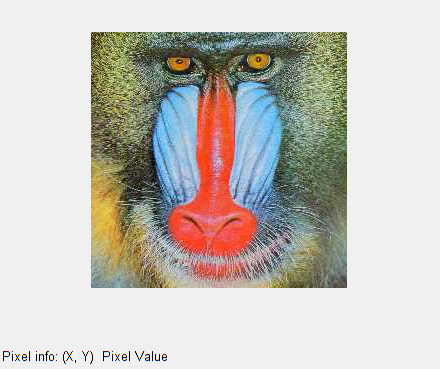

IM=imread('baboon.jpg');
imshow(IM);
impixelinfo

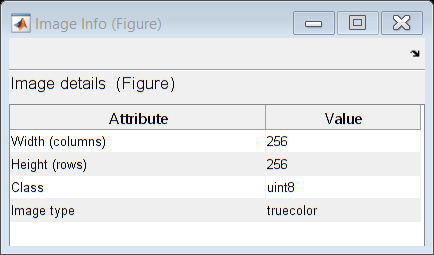

imageinfo

imfinfo('baboon.jpg')

ans = struct with fields:
           Filename: 'D:\OneDrive - uantwerpen\UAsem5\DIP\Lab1\baboon.jpg'
        FileModDate: '29-Oct-2020 15:55:14'
           FileSize: 14296
             Format: 'jpg'
      FormatVersion: ''
              Width: 256
             Height: 256
           BitDepth: 24
          ColorType: 'truecolor'
    FormatSignature: ''
    NumberOfSamples: 3
       CodingMethod: 'Huffman'
      CodingProcess: 'Progressive'
            Comment: {}


size(IM)

ans =    256   256     3



fprintf("show value of IM(10,15): %d",IM(10,15))

show value of IM(10,15): 62

fprintf("------------------------------------------\n\n------------------------------------------")

------------------------------------------

------------------------------------------

## Image to gray

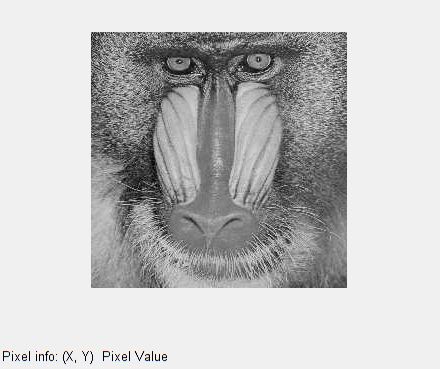

IMgray= rgb2gray(IM);
imshow(IMgray)

impixelinfo

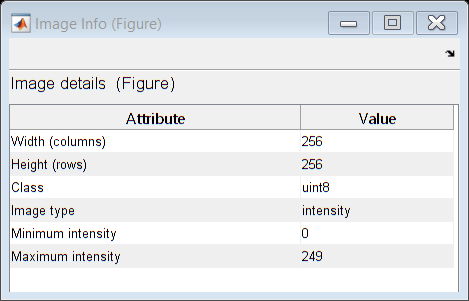

imageinfo

imfinfo('baboon.jpg')

ans = struct with fields:
           Filename: 'D:\OneDrive - uantwerpen\UAsem5\DIP\Lab1\baboon.jpg'
        FileModDate: '29-Oct-2020 15:55:14'
           FileSize: 14296
             Format: 'jpg'
      FormatVersion: ''
              Width: 256
             Height: 256
           BitDepth: 24
          ColorType: 'truecolor'
    FormatSignature: ''
    NumberOfSamples: 3
       CodingMethod: 'Huffman'
      CodingProcess: 'Progressive'
            Comment: {}


size(IMgray)

ans =    256   256



fprintf("show value of IM(10,15): %d",IMgray(10,15))

show value of IM(10,15): 60

fprintf("------------------------------------------\n\n------------------------------------------")

------------------------------------------

------------------------------------------

## image to binary

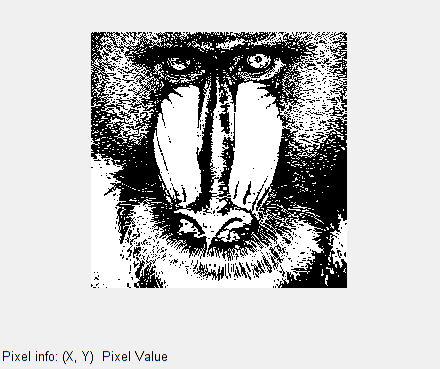

IMbin=imbinarize(IMgray);
imshow(IMbin)

impixelinfo

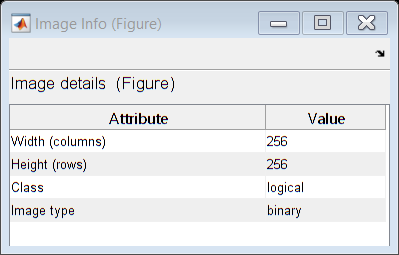

imageinfo

imfinfo('baboon.jpg')

ans = struct with fields:
           Filename: 'D:\OneDrive - uantwerpen\UAsem5\DIP\Lab1\baboon.jpg'
        FileModDate: '29-Oct-2020 15:55:14'
           FileSize: 14296
             Format: 'jpg'
      FormatVersion: ''
              Width: 256
             Height: 256
           BitDepth: 24
          ColorType: 'truecolor'
    FormatSignature: ''
    NumberOfSamples: 3
       CodingMethod: 'Huffman'
      CodingProcess: 'Progressive'
            Comment: {}


size(IMbin)

ans =    256   256



fprintf("Show value of IM(10,15): %d",IMbin(10,15))

Show value of IM(10,15): 0

fprintf("------------------------------------------\n\n------------------------------------------")

------------------------------------------

------------------------------------------

## Image to indexed

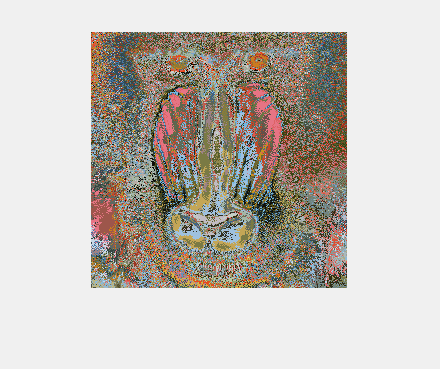

[IMind,map]= rgb2ind(IM,128);
imshow(IMind)
colormap(map)

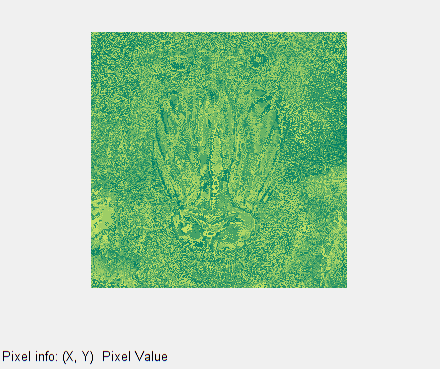


[IMind,map]= rgb2ind(IM,200);
imshow(IMind)
colormap('summer')

impixelinfo

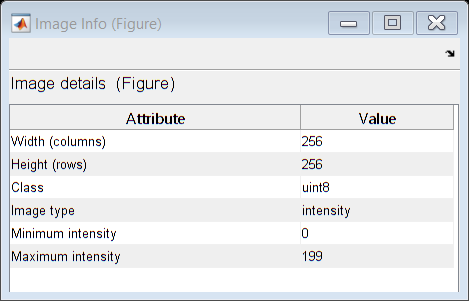

imageinfo

imfinfo('baboon.jpg')

ans = struct with fields:
           Filename: 'D:\OneDrive - uantwerpen\UAsem5\DIP\Lab1\baboon.jpg'
        FileModDate: '29-Oct-2020 15:55:14'
           FileSize: 14296
             Format: 'jpg'
      FormatVersion: ''
              Width: 256
             Height: 256
           BitDepth: 24
          ColorType: 'truecolor'
    FormatSignature: ''
    NumberOfSamples: 3
       CodingMethod: 'Huffman'
      CodingProcess: 'Progressive'
            Comment: {}


size(IMind)

ans =    256   256




fprintf("show value of IM(10,15): %d",IMind(10,15))

show value of IM(10,15): 10

fprintf("------------------------------------------\n\n------------------------------------------")

------------------------------------------

------------------------------------------

## part b: 

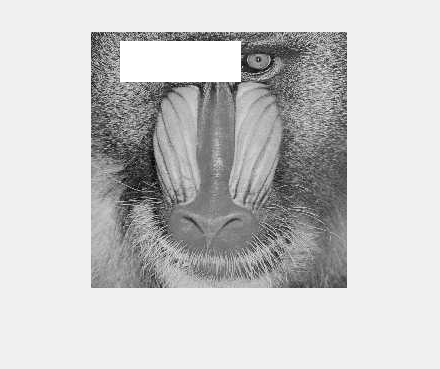

%- what is the effect of following command?
%IM(10:50,30:150)=255 

IMgray(10:50,30:150)=255;
imshow(IMgray)

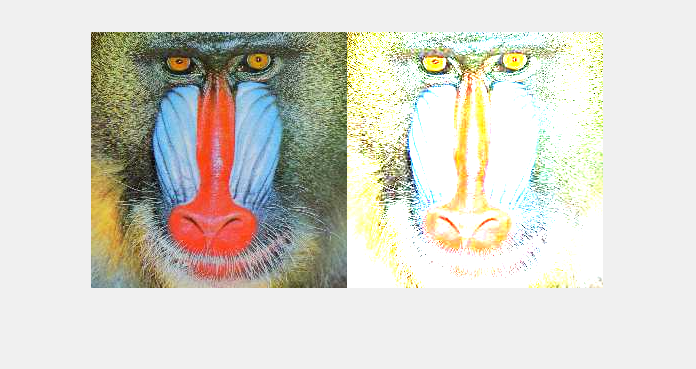


%IM1 = intensity halfed, IM2= intensity tripled
IM1=IM/2;
IM2=IM*3;
imshowpair(IM,IM2,'montage')